clear all; close all; clc;

e = .9;
%r = 0:250; % Turn radius m
A = 28; % geuss at Aspect Ratio
rho = 1.0834; % Density at a+*lt
%[~, ~, ~, rho] = atmosisa(convlength(3000, 'ft', 'm'));

%W2S = 450;%linspace(250:550,length(r)); % Wing Loading N/m^2
%W2S = 280; % to mathc figure 89 of Thomas
%W2S = 450 % messing with wing loading


% estimate values based on DG-100
% L_Dmax = 22.82;
% C_L_max = (pi * A * e) / (2 * L_Dmax); % Maximum lift coefficient of DG-1000
% %C_L_max = 2.7 % Maximum lift coefficient of PAH wing
% C_D_max = 2 * (C_L_max^2)/(pi * A * e); % Maximum drag coefficient
% C_D_0 = C_D_max / 2; % Parasite drag coefficient


%for our aircraft
C_L_max = 2.5; % maximum achivevable lift coefficient

C_D_0 = 0.0081; % drag coefficient

%C_D_0 = C_D_0 + .008/2 % average of clean and morphing wing variant (from morphing du-89 paper)
C_D_0 = C_D_0 + .008 % fully Flapped

C_D_0 = 0.0161


% here i will use (C_L^3/2/C_D)_max i.e. maximum climb rate
C_L_maxClimb = 1.345 * (A*e)^(3/4) / C_D_0^(1/4);

% limit max climb rate C_L to no bigger than C_L_max
if C_L_maxClimb > 2.5
    C_L_maxClimb = 2.5
end

C_L_maxClimb = 2.5000

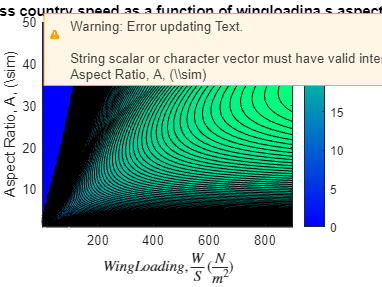



n_PlotPoints = 100; % 100 points runs in about 15 minutes 200 points takes several hours to run

W2S_min_plot = 1;
W2S_max_plot = 900;
A_min_plot = 1;
A_max_plot = 50;

W2Ss = linspace(W2S_min_plot, W2S_max_plot, n_PlotPoints);
As = linspace(A_min_plot, A_max_plot, n_PlotPoints);

for i = 1:length(W2Ss)
    W2S = W2Ss(i);
    V_ave_quast(i,:) = arrayfun(@(A) AverageCrossCountrySpeed_Quast(e, A, C_D_0, W2S, rho, C_L_maxClimb), As);
end

[W2Ssgrid, Asgrdid] = meshgrid(W2Ss,As);
%contour3(W2Ssgrid, Asgrdid, V_ave_quast, 1000, "LineWidth",.001), colormap("winter"); set(gca, "Color", [1,1,1]); colorbar;
contourf(W2Ssgrid, Asgrdid, V_ave_quast, 100, "LineWidth",.001), colormap("winter"); set(gca, "Color", [1,1,1]); colorbar; % for quick plots use 10 contours
title("average cross country speed as a function of wingloadina s aspect ratio");
zlabel("Average Cross Country Speed, V_ave, (m/s)",Interpreter="latex");

xlabel("Wing Loading, $\frac{W}{S}$, $(\frac{N}{m^2})$",Interpreter="latex");
ylabel("Aspect Ratio, $A$, $(\sim)$",Interpreter="latex");
% for i = 1:length(W2Ss)
%     W2S = W2Ss(i);
%     V_ave_quast(i) = AverageCrossCountrySpeed_Quast(e, A, C_D_0, W2S, rho, C_L_max);
% end
% plot(W2Ss, V_ave_quast); title("The optimum wingloading to maximise cross country speed",Interpreter="tex"); xlabel("$Wing Loading, \frac{W}{S} (\frac{N}{m^2})$",Interpreter="latex"), ylabel("Average Cross Country Speed, V_ave, (m/s)")